Select source data folder. Data folder shold have the following structure:

src_data

----damaged

----healthy

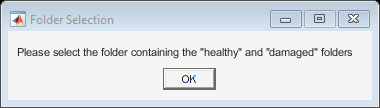

fileStruct = struct with fields:
    healthy: {1×19 cell}
    damaged: [1×1 struct]


fileStruct = struct with fields:
    healthy: {1×19 cell}
    damaged: [1×1 struct]


fileStruct = struct with fields:
    healthy: {1×19 cell}
    damaged: [1×1 struct]


fileStruct = struct with fields:
    healthy: {1×19 cell}
    damaged: [1×1 struct]


fileStruct = struct with fields:
    healthy: {1×19 cell}
    damaged: [1×1 struct]


[fileStruct, folderPathStruct] = selectFolderAndListFiles();

fileStruct: struct with the filenames of each folder ("healthy" and "damaged").

folderPath: absolute path of where folders "healthy" and "damaged" are located.

%%%%%%%%%%%

If "`Error using processTDMSFiles Specified TDMS file might be unsupported v1.0`"

Use the the live script **tscm.data_conversion.mlx**

%%%%%%%%%%%

fileList_healthy = fileStruct.healthy;
fileList_damaged_GF = fileStruct.damaged.GF_Ritzel;
%fileList_damaged_SIZA = fileStruct.damaged.SIZA_Graufleckigkeit_Ritzel_und_Rad;
%fileList_damaged_Gruebchen_Ritzel_Rad_leicht = fileStruct.damaged.Gruebchen_Ritzel_Rad_leicht;
fileList_damaged_Graufleckigkeit_Ritzel_schwer_Rad_leicht = fileStruct.damaged.Graufleckigkeit_Ritzel_schwer_Rad_leicht;
%fileList_damaged_Verschleiss_Ritzel_Rad_mittel = fileStruct.damaged.Verschleiss_Ritzel_Rad_mittel;

The struct has been divided in two lists, which are going to be converted into a struct of tables containing all files

decimateFactor = 10;

tdmsTables_healthy = processTDMSFiles(fileList_healthy, folderPathStruct.healthy, decimateFactor);
tdmsTables_damaged_GF = processTDMSFiles(fileList_damaged_GF, folderPathStruct.damaged.GF_Ritzel, decimateFactor);
%tdmsTables_damaged_SIZA = processTDMSFiles(fileList_damaged_SIZA, folderPathStruct.damaged.SIZA_Graufleckigkeit_Ritzel_und_Rad, decimateFactor);
%tdmsTables_damaged_Gruebchen_Ritzel_Rad_leicht = processTDMSFiles(fileList_damaged_Gruebchen_Ritzel_Rad_leicht, folderPathStruct.damaged.Gruebchen_Ritzel_Rad_leicht, decimateFactor);

tdmsTables_damaged_Graufleckigkeit_Ritzel_schwer_Rad_leicht = processTDMSFiles(fileList_damaged_Graufleckigkeit_Ritzel_schwer_Rad_leicht, folderPathStruct.damaged.Graufleckigkeit_Ritzel_schwer_Rad_leicht, decimateFactor);
%tdmsTables_damaged_Verschleiss_Ritzel_Rad_mittel = processTDMSFiles(fileList_damaged_Verschleiss_Ritzel_Rad_mittel, folderPathStruct.damaged.Verschleiss_Ritzel_Rad_mittel, decimateFactor);

tdmsTables_damaged_Graufleckigkeit_Ritzel_schwer_Rad_leicht_full = processTDMSFiles(fileList_damaged_Graufleckigkeit_Ritzel_schwer_Rad_leicht, folderPathStruct.damaged.Graufleckigkeit_Ritzel_schwer_Rad_leicht, 1);
tdmsTables_healthy_full = processTDMSFiles(fileList_healthy, folderPathStruct.healthy, 1);

%tableFeatures_healthy = extractTableFeatures(tdmsTables_healthy);
%tableFeatures_damaged_GF = extractTableFeatures(tdmsTables_damaged_GF);
%tableFeatures_damaged_SIZA = extractTableFeatures(tdmsTables_damaged_SIZA);
tableFeatures_damaged_Gruebchen_Ritzel_Rad_leicht = extractTableFeatures(tdmsTables_damaged_Gruebchen_Ritzel_Rad_leicht);
tableFeatures_damaged_Graufleckigkeit_Ritzel_schwer_Rad_leicht = extractTableFeatures(tdmsTables_damaged_Graufleckigkeit_Ritzel_schwer_Rad_leicht);
tableFeatures_damaged_Verschleiss_Ritzel_Rad_mittel = extractTableFeatures(tdmsTables_damaged_Verschleiss_Ritzel_Rad_mittel);

%exportTableToCSV(tableFeatures_healthy);

Table successfully exported to G:\Semester Arbeit\Programming\notebooks\csv_files\exported_table_healthy_fs_10kHz.csv


%exportTableToCSV(tableFeatures_damaged_GF);

Table successfully exported to G:\Semester Arbeit\Programming\notebooks\csv_files\exported_table_damaged_fs_10kHz.csv


%exportTableToCSV(tableFeatures_damaged_SIZA);

exportTableToCSV(tableFeatures_damaged_Gruebchen_Ritzel_Rad_leicht);

Table successfully exported to G:\Semester Arbeit\Programming\notebooks\csv_files\damaged_gruebchen_Ritzel_Rad_leicht_10_kHz.csv


exportTableToCSV(tableFeatures_damaged_Graufleckigkeit_Ritzel_schwer_Rad_leicht);

Table successfully exported to G:\Semester Arbeit\Programming\notebooks\csv_files\damaged_Graufleckigkeit_Ritzel_schwer_Rad_leicht_10_kHz.csv


exportTableToCSV(tableFeatures_damaged_Verschleiss_Ritzel_Rad_mittel);

Table successfully exported to G:\Semester Arbeit\Programming\notebooks\csv_files\damaged_Verschleiss_Ritzel_Rad_mittel_10_10kHz.csv
